data = ulogreader("log_11_2023-3-22-17-19-42.ulg")

data =   ulogreader with properties:

            FileName: "log_11_2023-3-22-17-19-42.ulg"
           StartTime: 00:01:02.714798
             EndTime: 00:09:09.029858
     AvailableTopics: [6×5 table]
    DropoutIntervals: [0×2 duration]


msg = readTopicMsgs(data)

msg = 6×6 table
              TopicNames              InstanceID    StartTimestamp      LastTimestamp         TopicMessages         MsgFormat  
    ______________________________    __________    _______________    _______________    _____________________    ____________

    "actuator_controls_0"                 0         00:01:02.823562    00:09:09.029858    { 97329×2  timetable}    { 3×3 table}
    "mission_result"                      0         00:00:14.288952    00:00:14.288952    {     1×14 timetable}    {15×3 table}
    "sensor_combined"                     0         00:01:02.822889    00:09:09.029253    { 97329×6  timetable}    { 8×3 table}
    "vehicle_angular_acceleration"        0         00:01:02.825757    00:09:09.029625    {136511×2  timetable}    { 4×3 table}
    "vehicl

systeminfo = readSystemInformation(data)

systeminfo = 15×2 table
      InformationField                        Value                   
    ____________________    __________________________________________

    "ver_sw"                "8733b82a20f5596f312a5de7fdf68783308a4767"
    "ver_sw_release"        "v1.12.3.alpha"                           
    "ver_hw"                "PX4_FMU_V5"                              
    "ver_hw_subtype"        "V500"                                    
    "sys_name"              "PX4"                                     
    "sys_os_name"           "NuttX"                                   
    "ver_sw_branch"         "system_id"                               
    "sys_os_ver"            "bf660cba2af81f055002b3817c87b1f63a78fd09"
    "sys_os_ver_release"    "134349055"                               
    "sys_toolchain"         "GNU GCC"                                 
    "sys_toolchain_ver"     "9.3.1 20200408 (release)" 

params = readParameters(data)

params = 878×2 table
        Parameters        Values
    __________________    ______

    "ASPD_BETA_GATE"           1
    "ASPD_BETA_NOISE"        0.3
    "ASPD_DO_CHECKS"           0
    "ASPD_FALLBACK_GW"         0
    "ASPD_FS_INNOV"            1
    "ASPD_FS_INTEG"           -1
    "ASPD_FS_T_START"         -1
    "ASPD_FS_T_STOP"           2
    "ASPD_PRIMARY"             1
    "ASPD_SCALE"               1
    "ASPD_SCALE_EST"           0
    "ASPD_SC_P_NOISE"     0.0001
    "ASPD_TAS_GATE"            3
    "ASPD_TAS_NOISE"         1.4
    "ASPD_W_P_NOISE"         0.1
    "BAT1_A_PER_V"        36.367


loggedoutput = readLoggedOutput(data)

loggedoutput = 987×2 timetable
       timestamp       LogLevel                                          Messages                                      
    _______________    _________    ___________________________________________________________________________________

    00:01:02.712845    "INFO"       "[logger] [logger] /fs/microsd/log/2023-03-22/16_11_35.ulg"                        
    00:01:02.714779    "INFO"       "[logger] Opened full log file: /fs/microsd/log/2023-03-22/16_11_35.ulg"           
    00:01:02.766110    "INFO"       "[logger] Start file log (type: mission)"                                          
    00:01:02.786828    "INFO"       "[logger] Opened mission log file: /fs/microsd/mission_log/2023-03-22/16_11_35.ulg"
    00:01:33.022752    "INFO"       "[mavlink] Starting mavli

plotter = flightLogSignalMapping("ulog");
info(plotter,"Signal",["actuator_controls_0" "sensor_combined" "vehicle_angular_acceleration" "vehicle_global_position"])

ans = 4×4 table
              SignalName              IsMapped    SignalFields    FieldUnits 
    ______________________________    ________    ____________    ___________

    "actuator_controls_0"              false      "Undefined"     "Undefined"
    "sensor_combined"                  false      "Undefined"     "Undefined"
    "vehicle_angular_acceleration"     false      "Undefined"     "Undefined"
    "vehicle_global_position"          false      "Undefined"     "Undefined"


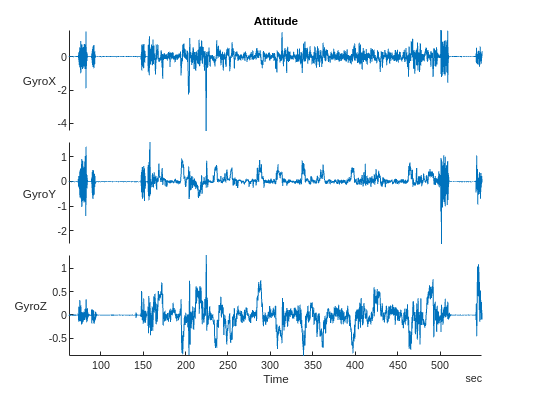

show(plotter,data)

d1 = data.StartTime;
d2 = d1 + duration([0 0 55],'Format','hh:mm:ss.SSSSSS');
log = readLoggedOutput(data,'Time',[d1 d2]);